# Team doubleE - Task 2, Option 1 Report

**Team Members: Andrew Wunderlich, Jay Desai, Miles Leonard-Albert **

***CSCE585 - Machine Learning Systems***

***Fall 2020 Adversarial ML Project***

This report provides insight and analysis into Task 2, in which we create adversarial examples using the Athena framework and test the adversarial examples against several defenses to compare performance.  This report was created in MATLAB as a live script (.mlx file) and exported to a PDF.

clear variables %reset workspace
close all; %close plots from previous runs
% projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

## Import Project Data and Analyze Composition

All labels and prediction data from the Task 2 assignment was dumped into a single file [\data\dataTable.mat] which contains a single matrix of digits.  Each row corresponds to a single sample (image) from the test dataset. The leftmost column contains the correct labels, and the following columns contain the predictions made by Athena for each of the tested whitebox attacks. 

### Load labels and raw prediction data

%load Task 1 data to get predictions of the undefended model on benign
%samples.  Needed for determining real error rates.
load('..\Task 1\results\predictionData.mat') 
clear predictions labels %clear other unneeded variables from Task 1


load('data\dataTable.mat') %load task 2 data
labels = dataTable(:,1);
predictions = dataTable(:,2:end);
pred_bs_um = pred_bs_um(1:length(labels))';


num_images = size(predictions,1);   % rows
num_attacks = size(predictions,2);  % columns

if(length(labels) ~= num_images) 
    error('Number of labels not equal to number of images. Please check dimensions.')
end

### Analyze Composition by Labels

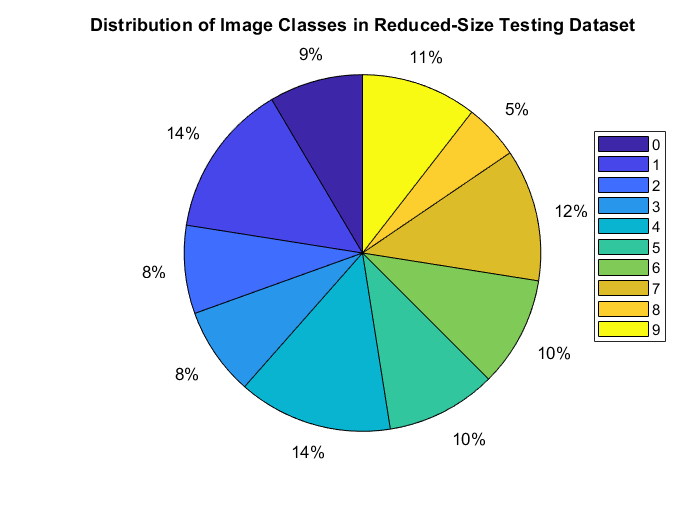

digits = unique(labels);
digitCounts = zeros(size(digits));
for i = 1:length(labels)
    for j = 1:length(digits)
        if(labels(i) == digits(j))
            digitCounts(j) = digitCounts(j) + 1;
            break;
        end
    end
end
pie(digitCounts);  title('Distribution of Image Classes in Reduced-Size Testing Dataset');
legend(string(digits), 'Position', [0.85 0.45 0.1 0.2]);

## Details About Attacks

This task includes 10 attacks, featuring the two supported whitebox attacks--FGSM and PGD--each at 5 different intensities.  Below we plot a few examples of images from the MNIST dataset modified using the following attacks:

### FGSM

with espilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

In each case, we used optimization-based whitebox approach presented in the Athena paper, which combines the Expectation Over Transformation (EOT) method with Random Self Ensemble (RSE) to create an optimization-based whitebox attack method targeted at an ensemble defense.

For each of the whitebox FGSM attacks, we selected a distribution with 1000 samples and a rotational transformation with angle in the range [-45°,45°].  While it would be interesting to change the distribution parameters and explore the effect on the adversarial system, in this experiment we elected to keep the distribution parameters constant so we could do a univariate analysis on the effect of the attack strength.  The five images below show the whitebox-attacked images at the five tested attack strengths.

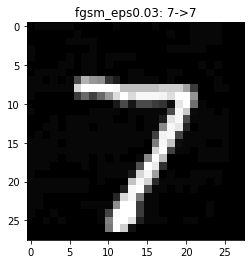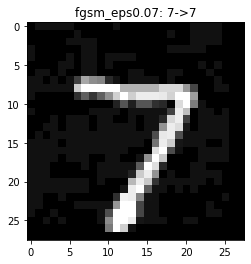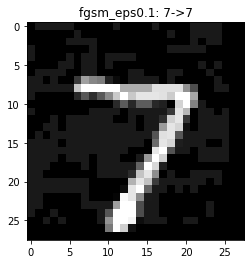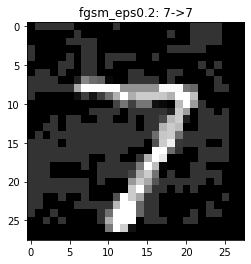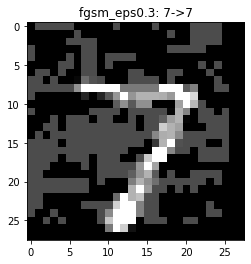

More information about the FGSM attack is available at [https://arxiv.org/abs/1412.6572](https://arxiv.org/abs/1412.6572).

### PGD

with epsilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

For each of the whitebox PGD attacks, we selected a distribution with 500 samples and a translational transformation with offset in the range [-0.2°,0.2°].  We again elected to keep the distribution parameters constant across the five PGD variants so we could do a univariate analysis on the effect of the attack strength.  The five images below show the whitebox-attacked images at the five tested attack strengths.

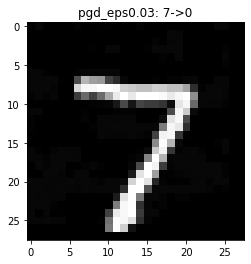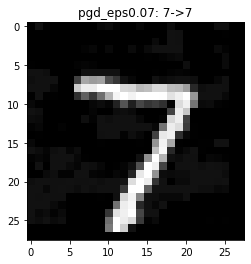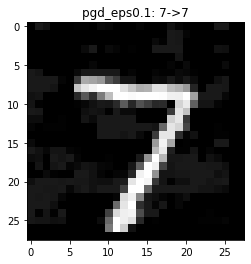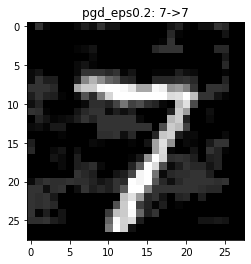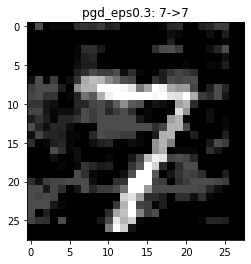

More information about the PGD attack is available at [https://arxiv.org/pdf/1706.06083.pdf](https://arxiv.org/pdf/1706.06083.pdf).

## Details about the Defense

Since whitebox attacks are crafted specifically according to the chosen defense, we only considered the Athena ensemble defense in this work.  In particular, we tested with the MV-20 variant--that is, "Vanilla Athena" with the Majority Voting ensemble strategy, using 20 weak defenses.

To have an apples-to-apples comparison with the blackbox attacks of Task 1, we used the same set of 20 weak defenses selected in the MV-20 of Task 1.  These weak defenses were chosen somewhat arbitrarily, but we made sure to choose a diverse set of weak defenses.

## Analyzing Error Rates

We generated 2000 perturbed images (10 attack variants * 200 of the 10,000 test images in MNIST) and obtained predictions for each.  We stored the 200 correct values (labels) and stored the 2000 predicted values for each adversarial example vs the Athena defense in an array, from which we can calculate error rates and plot relevant variables.

### Calculate Error Rates

errortable = -ones(size(predictions));
all_err_rates = -ones(1,num_attacks);

for i = 1:num_attacks
    %To be error, the prediction must not match the label, and the
    %label must have been correctly identified but the undefended model
    %before the attack (i.e. against the benign samples)
    errortable(:,i) = ((predictions(:,i) ~= labels) & (labels == pred_bs_um)); 
    
    %The error rate is simply the average of error values across the row
    all_err_rates(i) = mean(errortable(:,i));
end

### Plot Error Rates for Each EOT Whitebox Attack

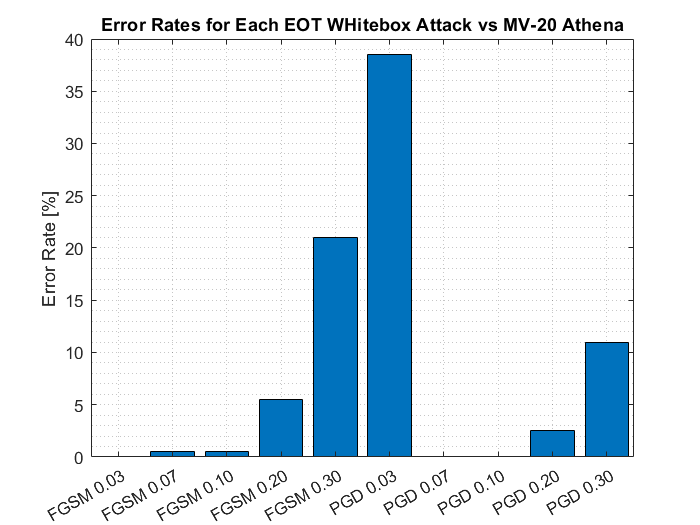

attacks = {'FGSM 0.03' 'FGSM 0.07' 'FGSM 0.10' 'FGSM 0.20' 'FGSM 0.30'...
            'PGD 0.03' 'PGD 0.07' 'PGD 0.10' 'PGD 0.20' 'PGD 0.30'};        
bar(categorical(attacks), all_err_rates(:)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each EOT Whitebox Attack vs MV-20 Athena');

The results are very interesting.  We would expect that in general, a stronger attack will always be more effective than a weaker attack.  This is true for all of the attacks observed above except for one very notable exception.  The weakest PGD attack, with epsilon of just 0.03, is by far the most effective whitebox attack of the ten tested.  When the attack strength is increased slightly (see PGD 0.07 and PGD 0.10), the error rate drops from 38.5% to exactly 0%, indicating that the stronger attacks could not sucessfully fool the defense on a single one of the 200 samples.

The effectiveness of such a low intensity attack would present a sigificant problem for the defense, as the perturbation induced on the image is evident at this level.  We refer the reader to the perturbed images from the previous section of the report.  Notice that the PGD 0.03 attack successfully fools the defense into misclassifying the 7 as a 0, but the image itself looks virtually the same as the unperturbed benign sample.

## Comparison with Black-box attacks from Task 1

The following figure was produced as part of Task 1, and considers blackbox attacks targeted at the undefended model.

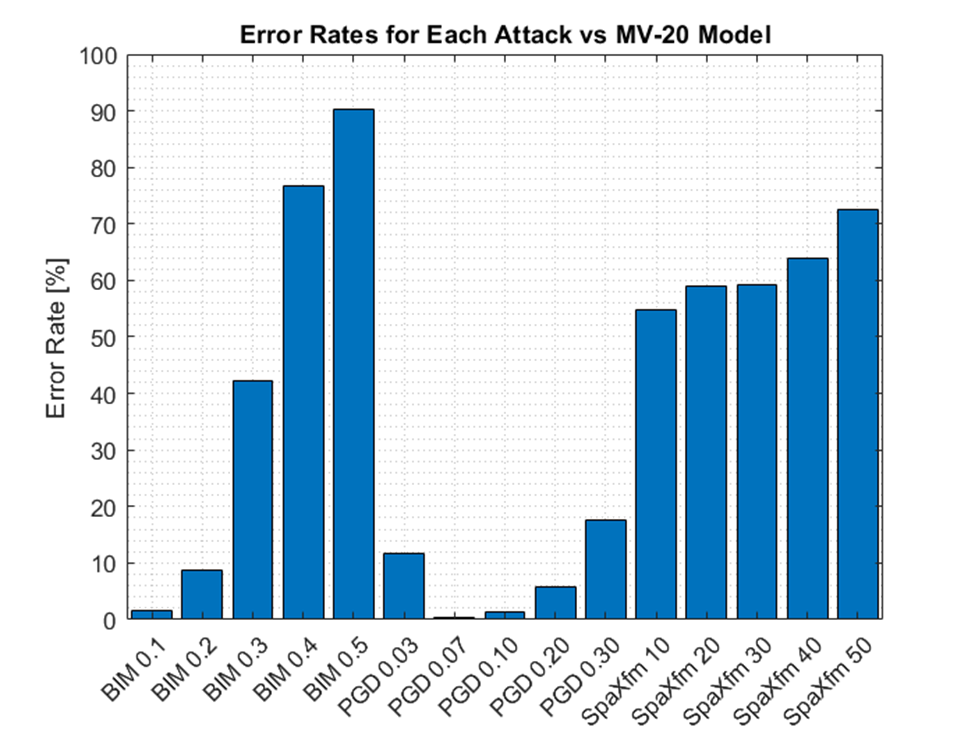

Note that FGSM was not one of the chosen attacks in our Task 1, so we do not have a blackbox FGSM to compare with.  However, comparing the whitebox PGD with the blackbox PGD, we do get some more interesting and counterintuitive results.  

First, we note that the outlier with the PGD 0.03 attack was present for blackbox attacks as well, though to a lesser extent.  The effective rate of the blackbox PGD 0.03 against MV-20 was ~12%, which fell between the effective rate of blackbox PGD 0.2 and 0.3.  In contrast, we noted that whitebox PGD 0.03 was drastically more effective than both whitebox PGD 0.2 and whitebox PGD 0.3.  In summary, the PGD 0.03 outlier was present in both experiments, but was signifcantly more of an outlier in the whitebox experiments than the blackbox experiments.

Second, comparing the other PDG attacks against the MV-20 defense, we note that the blackbox attacks had a higher success rate than the whitebox attacks.  This is very counterintuitive, as the whitebox attack is the strongest of all the attack types because it has full knowledge of the defense ensemble.

The reasons for these unexpected results are not clear, but we can speculate a few possible contributing factors which may be causing the unexpected results:

- It is possible that the optimization-based whitebox error rates different for the full MNIST dataset than for the subset we tested with, because we limited the analysis to 200 of the 15,000 images.  The dataset size had to be cut strongly simply because of the high computational cost of generating optimization-based whitebox attacks for the 20-weak-defense ensemble. Even using only 200 images for each of the ten tested attacks, the script which produced the attacks and evaluated them against the defense took about 24 hours to run on a laptop PC.   This runtime could be dramatically reduced in a number of ways, such as: using GPU(s) rather than the laptop CPU, offloading the job to a supercomputer, or compressing the models using pruning and quantizing techniques.  However, since all of these runtime improvements are beyond the scope of the project, we were forced to dramatically cut the dataset to achieve reasonable execution times.

- The PGD 0.03 outlier may be a result of a poorly chosen set of weak defenses in the ensemble.  This would also make sense because the chosen WDs were common to the Task 1 blackbox attacks and Task 2 whitebox attacks, and the outlier was present in both cases.

In general, the experimental infrastructure used provided a very large number of adjustable parameters, which made it impossible to explore the entire trade space of attacks and defenses.  Adjustable parameters in this experiment would include:

- The number of weak defenses in the ensemble

- The particular weak defenses selected, including the types of WD and the number of each type used

- The ensemble strategy selected

- The strength of the whitebox attacks, which is itself a function of numerous attack-specific parameters

- The distribution of transformations for the attacks (when using EOT), including the number of samples in the distribution, the 

- The subset of the MNIST dataset that we would work with

We could have altered all of these parameters in the experiment and gotten results, but this would make it very difficult to interpret the underlying causes for the output data.  Instead, we opted to keep most of the parameters constant and vary just a few in order to get more easily interprettable results and establish logical correlations which help us to draw conclusions from the data.  The drawback of this apporach is that there remains a large space of unexplored territory which we do not get to see when keeping most of the parameters constant.  

### Another note about computational cost

 We noted about that computational cost constraints limited the size of our test dataset severely enough to possibly skew error rate results.  However, we should also note that the high computational cost of whitebox attacks against the ensemble is **a feature of the defense** which limits the feasibility of attackers running whitebox attacks in the first place.  Thus, ironically, the feature that potentially skewed the analysis of the defense is also itself a strong argument that the defense is strong.

## Suggested Future Work

- Explore the space around the PGD 0.03 attack, (with whitebox and/or blackbox approaches) to get a better understanding on why this weak attack was so effective.  For example, try PGD with epsilons of 0.01, 0.02, 0.03, 0.04, 0.05.  How do these attacks perform?

- Alter the selection of weak defenses and rerun the experiments, checking if the PGD 0.03 outlier remains and if the whitebox attack methods still produce low error rates.

## Non-EOT Based Whitebox Attacks

Since the results for the EOT-based whitebox attacks above were surprising, we decided to generate a second set of whitebox attacks which were identical but which did not use the EOT generation method.  We found that these were much less computationally expensive, but for direct comparison with the EOT attacks, we used exactly the same 200 images with exactly the same attack parameters.

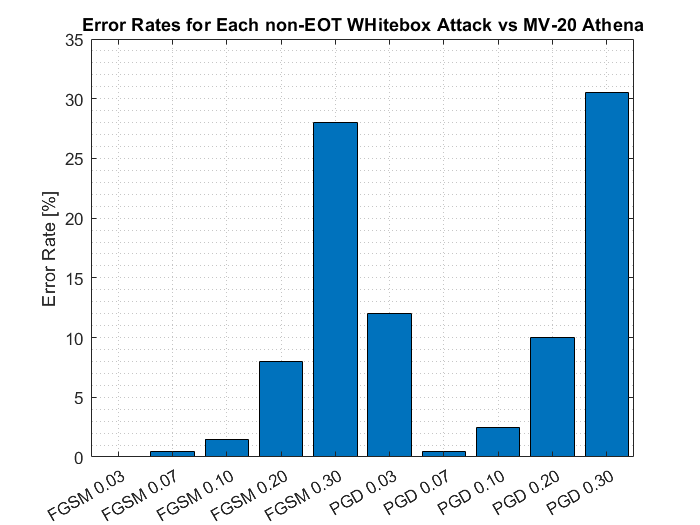

load('data/dataTable2.mat')
predictions = dataTable2(:,2:end);

errortable = -ones(size(predictions));
all_err_rates = -ones(1,num_attacks);

for i = 1:num_attacks
    %To be error, the prediction must not match the label, and the
    %label must have been correctly identified but the undefended model
    %before the attack (i.e. against the benign samples)
    errortable(:,i) = ((predictions(:,i) ~= labels) & (labels == pred_bs_um)); 
    
    %The error rate is simply the average of error values across the row
    all_err_rates(i) = mean(errortable(:,i));
end

bar(categorical(attacks), all_err_rates(:)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each non-EOT WHitebox Attack vs MV-20 Athena');

We can see here that while the PGD 0.03 attack is still more effective than stronger attacks like PGD 0.07 and PGD 0.10, the difference is more moderate, and the PGD 0.30 attack now outperforms all of the weaker attacks.  This is more on par with what we saw in the blackbox attacks from Task 1.

Additionally, we see that the non-EOT whitebox attacks are more effective than the EOT whitebox attacks and also more effective than the blackbox attacks.  While the non-EOT FGSM attacks show improvement over the EOT FGSM attacks, the difference is even more pronounced for the PGD attacks.  For example, the EOT PGD 0.30 error rate was just 11%, while the non-EOT PGD 0.30 error rate was 30.5%.

## Final Conclusions

Overall, the EOT-based whitebox attacks studied in this task did not perform well.  The error rate generated by the attacks against Athena (using 20 WD's with Majority Voting) was lower than for non-EOT whitebox attacks and actually even lower than blackbox attacks in most cases.  Additionally, we found that the EOT attacks were easily an order of magnitude more computationally expensive than the non-EOT attacks, so much so that we had to drastically cut the dataset size to complete the assignment.  Combining the worse performance and the significantly increased computational expense, we find no compelling reason for an attacker to use the EOT whitebox attack against Athena.  

We do not yet fully understand the remarkable performance of the PGD 0.03 attack in all tested attack types against Athena, and we believe this warrants further investigation.

## Team Member Contributions